# FitFromFigure.mlx

Illustrates fitting using a fit tool from a figure menu.

Opening a figure window provides access to some quick interactive fitting tools. This script creates a figure and illustrates the interactive fitting tool by using a script exported from such a tool. As such it is a model itself that you can use. Note that you do not have access to the fit parameter errors interactively. This script shows how to generate code from the figure window. By examining the code, we see what fitting routine was used and are then able to call the same fitting function and to extract the errors on the fit parameters.

Author: D. Carlsmith

### Initialize

clear all;% clear variables
delete(findall(0,'Type','figure'))% close all open figure windows

Generate example vectors x and y and a vector of errors on y and then an example plot. The script user can replace these with real data.

x = 1:10:100;
a=2;b=2; dev=10; %intercept and slope and standard deviation on y
% Generate y with common gaussian error added
y= a+b*x+dev*randn([1,length(x)]);
err = dev*ones(size(y));

err =     10    10    10    10    10    10    10    10    10    10


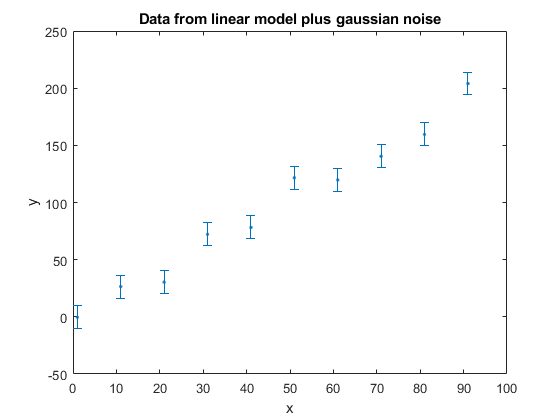

% Plot data with errors. Linespec= point with NO CONNECTING LINES.
errorbar(x,y,err,'.')
xlabel('x');ylabel('y');title('Data from linear model plus gaussian noise')

Open the plot just created in a separate window using the arrow icon at the upper right of the plot when it is executed in MATLAB. From the plot menus, select Tools=>Basic Fitting then, within the fitting menu that pops up,  select Linear, Show equations, Plot residuals, Bar plot, Subplot, and Show norm of residuals (calculated using the norm function, norm(V,2), where V is the vector of residuals) which is the square root of the sum of the squared residuals. I've saved those steps using from the plot Tools/Generate code and appended the functions (with end statements after each one) below to invoke. After you are done, a figure should appear like the one created below.

From the new figure, under Files select Generate code... An untitled file of of figure generation code will appear in the MATLAB editor window. Save this code with the file name createfigure.m or copy and paste it to a working script. If you copy and paste it to  .mlx script, you must add an 'end' at the end of every function within it.

Below generated code is attached. We call it now...

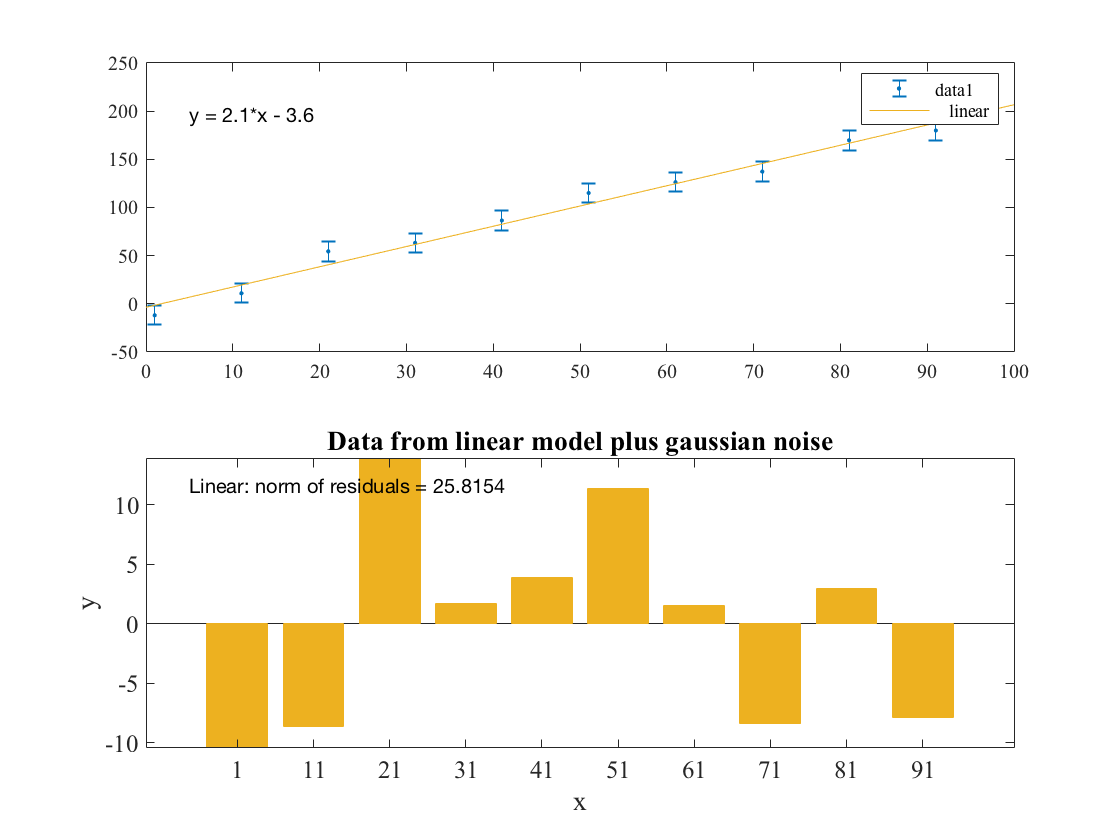

createfigure(x,y,err)

Notice the residuals appear nicely below the plot with the fit.  

The generated code t, with `end` added after each function, appear below.

Examine the code. You can see the fit was using the MATLAB function `polyfi`t. The line which performs the fit is

fitResults1 = polyfit(xdata1,ydata1,1);

Look up polyfit with MATLAB help and scroll therough the examples. You will find the following code, copied and pasted here:

[p,S] = polyfit(x,y,1); 

Evaluate the first-degree polynomial fit in p at the points in x. Specify the error estimation structure as the third input so that polyval calculates an estimate of the standard error. The standard error estimate is returned in delta.


[y_fit,delta] = polyval(p,x,S);

Plot the original data, linear fit, and 95% prediction interval .

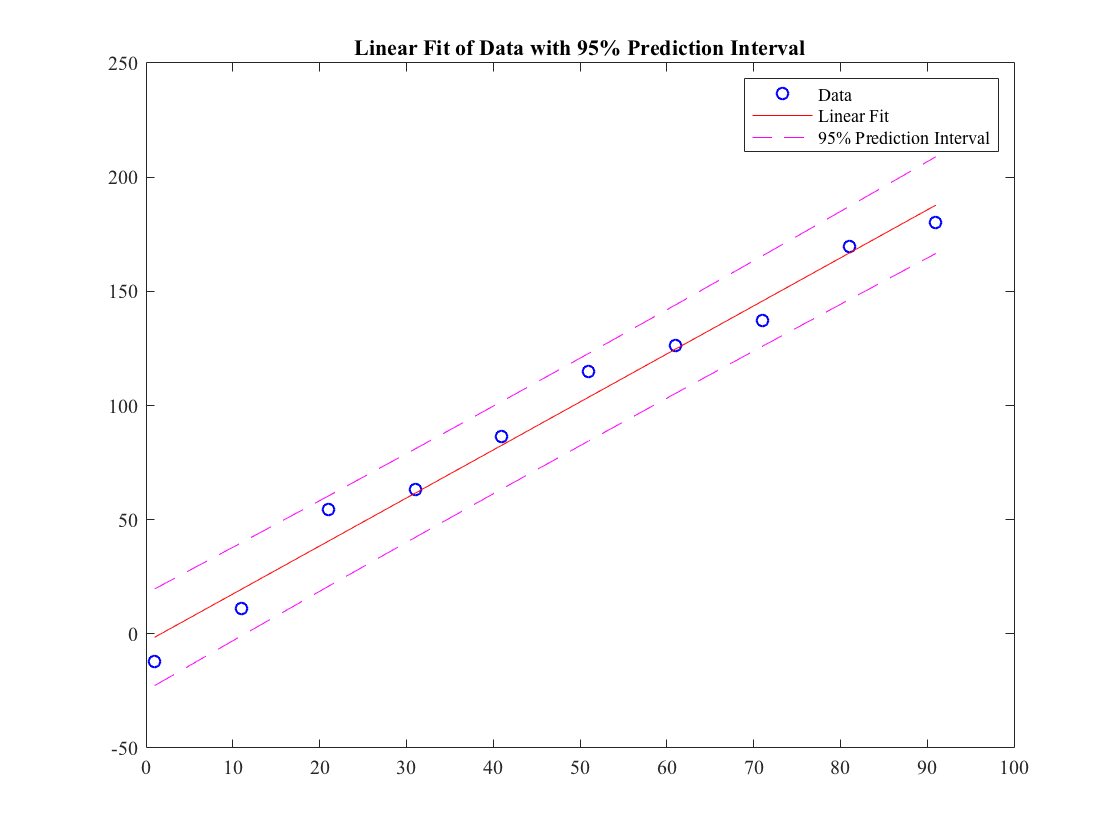

figure
plot(x,y,'bo')
hold on
plot(x,y_fit,'r-')
plot(x,y_fit+2*delta,'m--',x,y_fit-2*delta,'m--')
title('Linear Fit of Data with 95% Prediction Interval')
legend('Data','Linear Fit','95% Prediction Interval')

This code refits, capturing the fit parameter results in the vector `p` and additional information in the structure `S`. It then evaluates the fitted polynomial using `polyval` and then replots the data with 95% confidence levels.

Here are the parameter values:

slope=p(1)

slope =    2.102889572109230


intercept = p(2)

intercept =   -3.593380176904937


According to the polyfit documentation (help), If the data in `y` is random, then an estimate of the covariance matrix of `p` is `(Rinv*Rinv')*normr^2/df`, where `Rinv` is the inverse of `R`.

So to retrieve the stadard errors on the parameters, we do the following:

R=S.R;Rinv=inv(R);Cov=(Rinv*Rinv')*S.normr^2/S.df;
standarderrors = sqrt(diag(Cov))

standarderrors =    0.100486183517199
   5.449464957402994


To get the standard errors on the parameters

function createfigure(X1, Y1, D1)
%CREATEFIGURE(X1, Y1, D1)
%  X1:  errorbar x vector data
%  Y1:  errorbar y vector data
%  D1:  errorbar delta vector data

%  Auto-generated by MATLAB on 03-Oct-2018 14:00:25

% Create figure
figure1 = figure('NumberTitle','off','Name','LiveEditorFigure');

% Create axes
axes1 = axes('Parent',figure1,'Position',[0.13 0.5675 0.775 0.3575]);
hold(axes1,'on');

% Create errorbar
errorbar1 = errorbar(X1,Y1,D1,'DisplayName','data1','Marker','.',...
    'LineStyle','none');

% Get xdata from plot
xdata1 = get(errorbar1, 'xdata');
% Get ydata from plot
ydata1 = get(errorbar1, 'ydata');
% Make sure data are column vectors
xdata1 = xdata1(:);
ydata1 = ydata1(:);


% Remove NaN values and warn
nanMask1 = isnan(xdata1(:)) | isnan(ydata1(:));
if any(nanMask1)
    warning('GeneratedCode:IgnoringNaNs', ...
        'Data points with NaN coordinates will be ignored.');
    xdata1(nanMask1) = [];
    ydata1(nanMask1) = [];
end

% Find x values for plotting the fit based on xlim
axesLimits1 = xlim(axes1);
xplot1 = linspace(axesLimits1(1), axesLimits1(2));

% Prepare for plotting residuals
set(axes1,'position',[0.1300    0.5811    0.7750    0.3439]);
residAxes1 = axes('position', [0.1300    0.1100    0.7750    0.3439], ...
    'parent', gcf);
savedResids1 = zeros(length(xdata1), 1);
% Sort residuals
[sortedXdata1, xInd1] = sort(xdata1);

% Preallocate for "Show equations" coefficients
coeffs1 = cell(1,1);

% Find coefficients for polynomial (order = 1)
fitResults1 = polyfit(xdata1,ydata1,1);
% Evaluate polynomial
yplot1 = polyval(fitResults1,xplot1);

% Save type of fit for "Show norm of residuals" and "Show equations"
fittypesArray1(1) = 2;

% Calculate and save residuals - evaluate using original xdata
Yfit1 = polyval(fitResults1,xdata1);
resid1 = ydata1 - Yfit1(:);
savedResids1(:,1) = resid1(xInd1);
savedNormResids1(1) = norm(resid1);

% Save coefficients for "Show Equation"
coeffs1{1} = fitResults1;

% Plot the fit
fitLine1 = plot(xplot1,yplot1,'DisplayName','   linear','Tag','linear',...
    'Parent',axes1,...
    'Color',[0.929 0.694 0.125]);

% Set new line in proper position
setLineOrder(axes1,fitLine1,errorbar1);

% Plot residuals in a bar plot
residPlot1 = bar(residAxes1, sortedXdata1, savedResids1);
% Set colors to match fit lines
set(residPlot1(1), 'facecolor', [0.929 0.694 0.125],'edgecolor', [0.929 0.694 0.125]);
% Set residual plot axis title
title(residAxes1, 'residuals');

% "Show norm of residuals" was selected
showNormOfResiduals(residAxes1,fittypesArray1,savedNormResids1);

% "Show equations" was selected
showEquations(fittypesArray1,coeffs1,2,axes1);

% Create ylabel
ylabel('y','FontName','times');

% Create xlabel
xlabel('x','FontName','times');

% Create title
title('Data from linear model plus gaussian noise');

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[-11 103]);
box(axes1,'on');
% Create legend
legend(axes1,'show');
end
%-------------------------------------------------------------------------%
function setLineOrder(axesh1, newLine1, associatedLine1)
%SETLINEORDER(AXESH1,NEWLINE1,ASSOCIATEDLINE1)
%  Set line order
%  AXESH1:  axes
%  NEWLINE1:  new line
%  ASSOCIATEDLINE1:  associated line

% Get the axes children
hChildren = get(axesh1,'Children');
% Remove the new line
hChildren(hChildren==newLine1) = [];
% Get the index to the associatedLine
lineIndex = find(hChildren==associatedLine1);
% Reorder lines so the new line appears with associated data
hNewChildren = [hChildren(1:lineIndex-1);newLine1;hChildren(lineIndex:end)];
% Set the children:
set(axesh1,'Children',hNewChildren);
end
%-------------------------------------------------------------------------%
function showNormOfResiduals(residaxes1, fittypes1, normResids1)
%SHOWNORMOFRESIDUALS(RESIDAXES1,FITTYPES1,NORMRESIDS1)
%  Show norm of residuals
%  RESIDAXES1:  axes for residuals
%  FITTYPES1:  types of fits
%  NORMRESIDS1:  norm of residuals

txt = cell(length(fittypes1) ,1);
for i = 1:length(fittypes1)
    txt{i,:} = getResidString(fittypes1(i),normResids1(i));
end
% Save current axis units; then set to normalized
axesunits = get(residaxes1,'units');
set(residaxes1,'units','normalized');
text(.05,.95,txt,'parent',residaxes1, ...
    'verticalalignment','top','units','normalized');
% Reset units
set(residaxes1,'units',axesunits);
end
%-------------------------------------------------------------------------%
function [s1] = getResidString(fittype1, normResid1)
%GETRESIDSTRING(FITTYPE1,NORMRESID1)
%  Get "Show norm of residuals" text
%  FITTYPE1:  type of fit
%  NORMRESID1:  norm of residuals

% Get the text from the message catalog.
switch fittype1
    case 0
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplaySplineNorm'));
    case 1
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplayShapepreservingNorm'));
    case 2
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplayLinearNorm', num2str(normResid1)));
    case 3
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplayQuadraticNorm', num2str(normResid1)));
    case 4
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplayCubicNorm', num2str(normResid1)));
    otherwise
        s1 = getString(message('MATLAB:graph2d:bfit:ResidualDisplayNthDegreeNorm', fittype1-1, num2str(normResid1)));
end
end
%-------------------------------------------------------------------------%
function showEquations(fittypes1, coeffs1, digits1, axesh1)
%SHOWEQUATIONS(FITTYPES1,COEFFS1,DIGITS1,AXESH1)
%  Show equations
%  FITTYPES1:  types of fits
%  COEFFS1:  coefficients
%  DIGITS1:  number of significant digits
%  AXESH1:  axes

n = length(fittypes1);
txt = cell(length(n + 1) ,1);
txt{1,:} = ' ';
for i = 1:n
    txt{i + 1,:} = getEquationString(fittypes1(i),coeffs1{i},digits1,axesh1);
end
text(.05,.95,txt,'parent',axesh1, ...
    'verticalalignment','top','units','normalized');
end
%-------------------------------------------------------------------------%
function [s1] = getEquationString(fittype1, coeffs1, digits1, axesh1)
%GETEQUATIONSTRING(FITTYPE1,COEFFS1,DIGITS1,AXESH1)
%  Get "Show Equation" text
%  FITTYPE1:  type of fit
%  COEFFS1:  coefficients
%  DIGITS1:  number of significant digits
%  AXESH1:  axes

if isequal(fittype1, 0)
    s1 = 'Cubic spline interpolant';
elseif isequal(fittype1, 1)
    s1 = 'Shape-preserving interpolant';
else
    op = '+-';
    format1 = ['%s %0.',num2str(digits1),'g*x^{%s} %s'];
    format2 = ['%s %0.',num2str(digits1),'g'];
    xl = get(axesh1, 'xlim');
    fit =  fittype1 - 1;
    s1 = sprintf('y =');
    th = text(xl*[.95;.05],1,s1,'parent',axesh1, 'vis','off');
    if abs(coeffs1(1) < 0)
        s1 = [s1 ' -'];
    end
    for i = 1:fit
        sl = length(s1);
        if ~isequal(coeffs1(i),0) % if exactly zero, skip it
            s1 = sprintf(format1,s1,abs(coeffs1(i)),num2str(fit+1-i), op((coeffs1(i+1)<0)+1));
        end
        if (i==fit) && ~isequal(coeffs1(i),0)
            s1(end-5:end-2) = []; % change x^1 to x.
        end
        set(th,'string',s1);
        et = get(th,'extent');
        if et(1)+et(3) > xl(2)
            s1 = [s1(1:sl) sprintf('\n     ') s1(sl+1:end)];
        end
    end
    if ~isequal(coeffs1(fit+1),0)
        sl = length(s1);
        s1 = sprintf(format2,s1,abs(coeffs1(fit+1)));
        set(th,'string',s1);
        et = get(th,'extent');
        if et(1)+et(3) > xl(2)
            s1 = [s1(1:sl) sprintf('\n     ') s1(sl+1:end)];
        end
    end
    delete(th);
    % Delete last "+"
    if isequal(s1(end),'+')
        s1(end-1:end) = []; % There is always a space before the +.
    end
    if length(s1) == 3
        s1 = sprintf(format2,s1,0);
    end
end

end